FFT

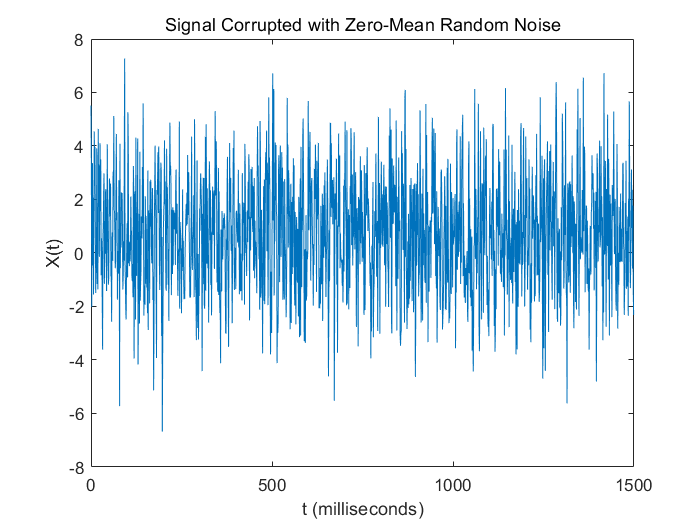

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector

S = 0.8 + 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
X = S + 2*randn(size(t));
plot(1000*t,X)
title("Signal Corrupted with Zero-Mean Random Noise")
xlabel("t (milliseconds)")
ylabel("X(t)")

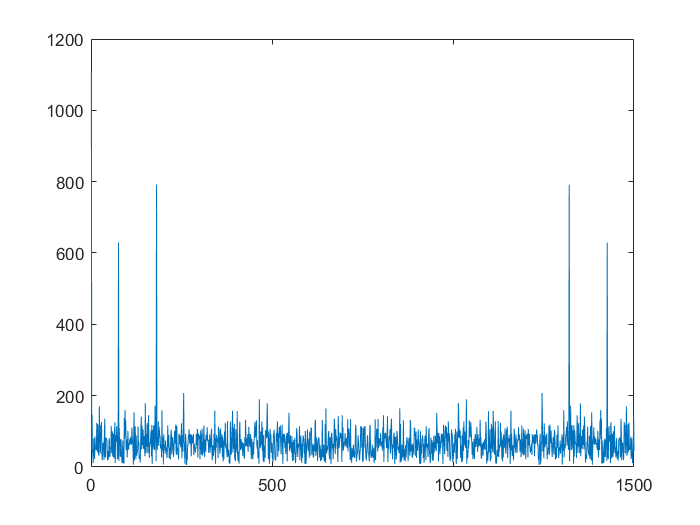


Y = fft(X);
plot(abs(Y))

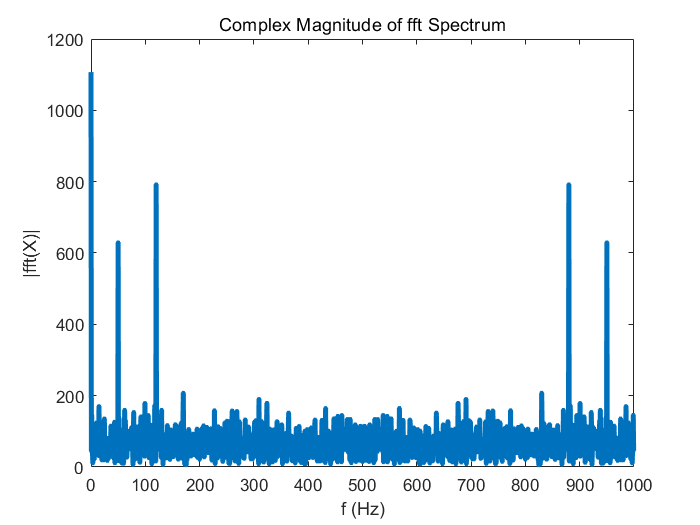

plot(Fs/L*(0:L-1),abs(Y),"LineWidth",3)
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")

该图显示五个频率峰值，包括 DC 偏移量在 0 Hz 处的峰值。在此示例中，信号预计在 0 Hz、50 Hz 和 120 Hz 处有三个频率峰值。此处，绘图的后半部分是前半部分的镜像，不包括 0 Hz 处的峰值。原因是时域信号的离散傅里叶变换具有周期性，其频谱的前半部分为正频率，后半部分为负频率，第一个元素保留用于零频率。

对于实信号，`fft` 频谱是双边频谱，其中正频率的频谱是负频率的频谱的复共轭。要显示正负频率的 `fft` 频谱，可以使用 `fftshift`。对于偶数长度 `L`，频域从奈奎斯特频率的负值 `-Fs/2` 开始，直到 `Fs/2-Fs/L`，间距或频率分辨率为 `Fs/L`。

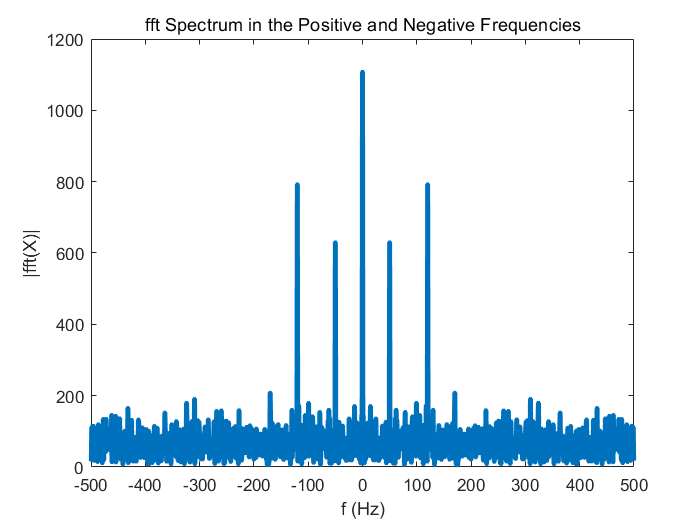

plot(Fs/L*(-L/2:L/2-1),abs(fftshift(Y)),"LineWidth",3)
title("fft Spectrum in the Positive and Negative Frequencies")
xlabel("f (Hz)")
ylabel("|fft(X)|")